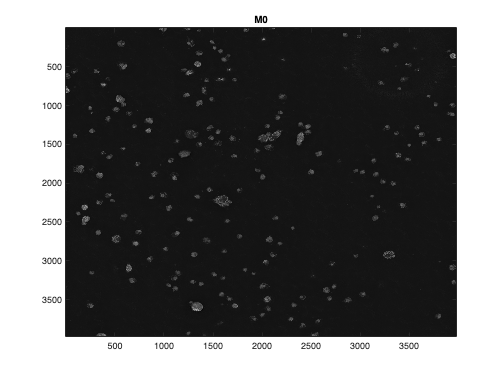

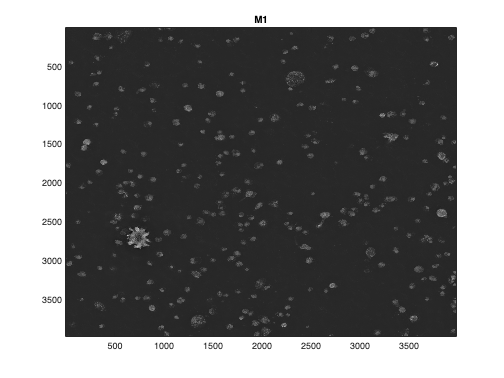

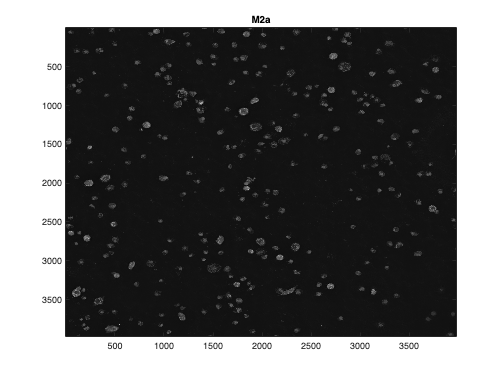

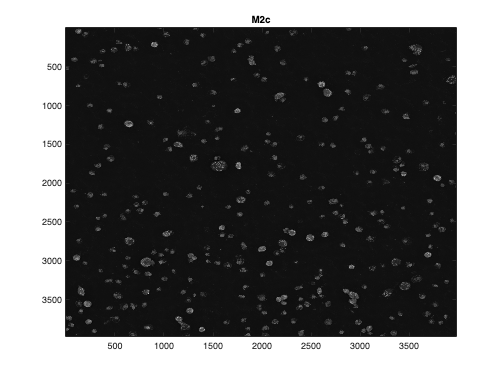

% INPUT

filenames = {"M0/M0.tiff", "M1/M1.tiff", "M2a/M2a.tiff", "M2c/M2c.tiff"};
images = cell(1, length(filenames));
titles = {"M0", "M1", "M2a", "M2c"};

for i = 1:length(filenames)
    tiff_obj = Tiff(filenames{i}, "r");
    images{i} = read(tiff_obj);
    close(tiff_obj);
end

for i = 1:length(images)
    figure;
    imagesc(images{i});
    colormap(gray(256));
    title(titles{i});
end

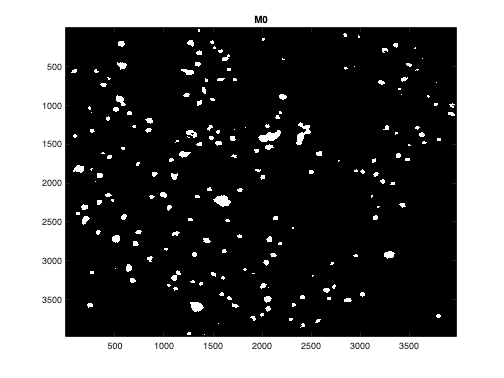

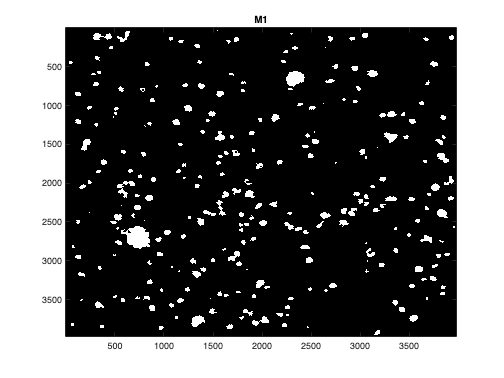

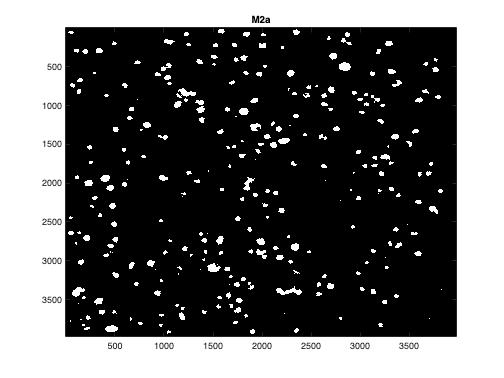

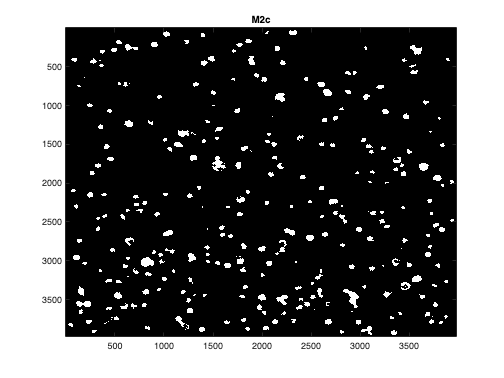

% PROCESSING

processed_images = cell(1, length(filenames));

for i = 1:length(images)
    
    [~, threshold] = edge(images{i}, 'sobel');
    fudge = 1;
    processed_images{i} = edge(images{i}, 'sobel', threshold * fudge);

    se90 = strel("line", 3, 90);
    se0 = strel("line", 3, 0);
    processed_images{i} = imdilate(processed_images{i}, [se90 se0]);

    img_fill = imfill(processed_images{i}, "holes");
    sc = strel("disk", 5);
    out_img = imclose(img_fill, sc);
    processed_images{i} = imclose(out_img, sc);

    processed_images{i} = imclearborder(processed_images{i}, 8);

    seD = strel("diamond", 4);
    img_final = imerode(processed_images{i}, seD);
    processed_images{i} = imerode(img_final, seD);
end

for i = 1:length(images)
    figure;
    imagesc(processed_images{i});
    colormap(gray(256));
    title(titles{i});
end

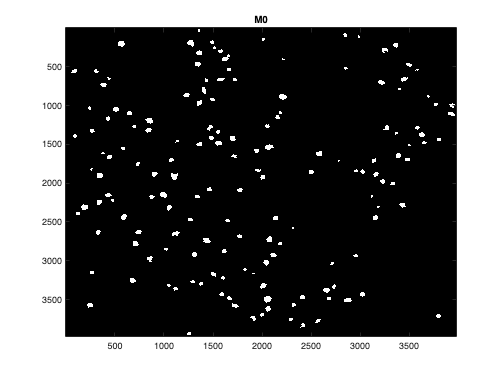

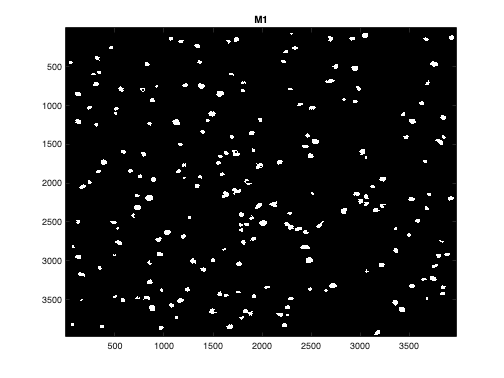

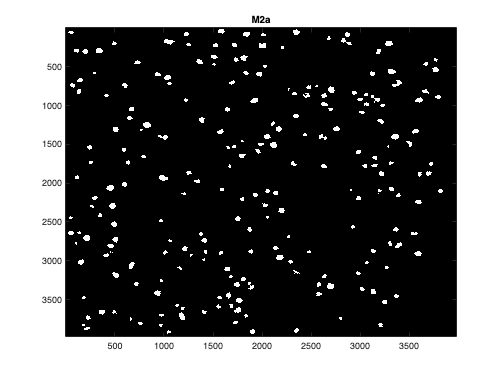

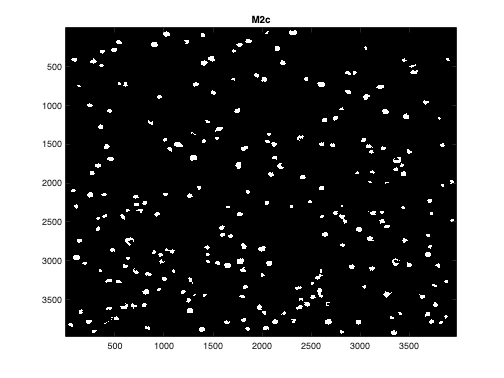

% FILTER

filtered_images = cell(1, length(filenames));

for i = 1:length(filenames)
    img_label = bwlabel(processed_images{i});
    bw = imbinarize(img_label);
    cc = bwconncomp(bw);
    stats = regionprops("table", cc, "Area");
    selection = (stats.Area > 500 & stats.Area < 5000);
    filtered_images{i} = cc2bw(cc, ObjectsToKeep=selection);
end

for i = 1:length(images)
    figure;
    imagesc(filtered_images{i});
    colormap(gray(256));
    title(titles{i});
end

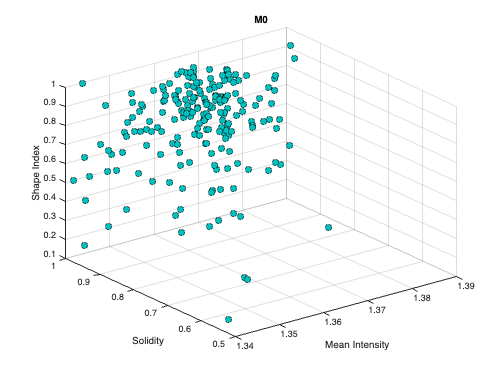

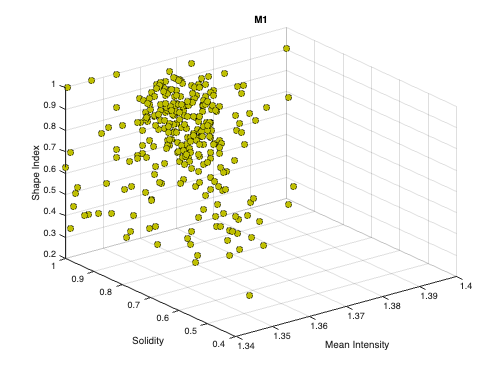

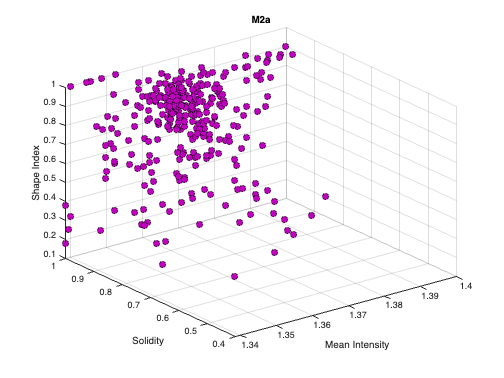

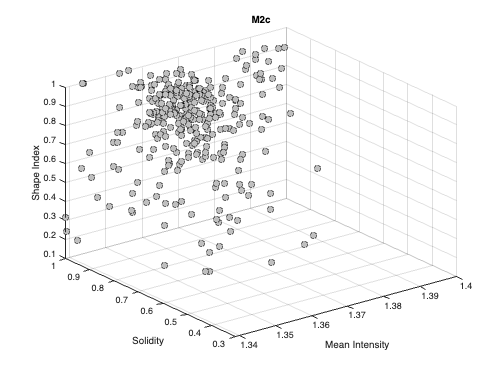

% INITAIL ASSESSMENT

color = {[0 .75 .75], [.75 .75 0], [.75 0 .75], [.75 .75 .75]};

for i = 1:length(filenames)
    label = processed_images{i} > 0;
    stats = regionprops(label, images{i}, 'MeanIntensity', 'Solidity', 'MajorAxisLength', 'MinorAxisLength');

    meanIntensity = [stats.MeanIntensity]';
    solidity = [stats.Solidity]';
    major = [stats.MajorAxisLength];
    minor = [stats.MinorAxisLength];
    shape_index = minor ./ major;
    
    figure
    scatter3(meanIntensity, solidity, shape_index, 50, 'filled', ...
        'MarkerEdgeColor', 'k',...
        'MarkerFaceColor', color{i})
    xlabel('Mean Intensity');
    ylabel('Solidity');
    zlabel('Shape Index');
    title(titles{i});
    grid on
end

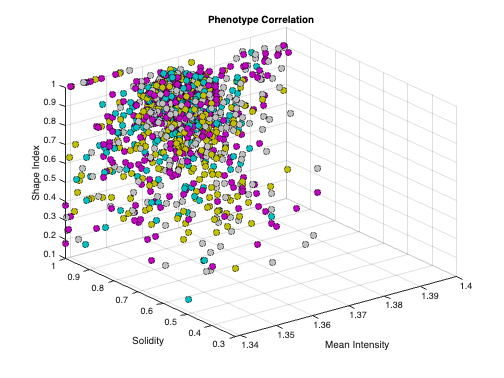

% CORRELATION PLOT

for i = 1:length(filenames)
    label = processed_images{i} > 0;
    stats = regionprops(label, images{i}, 'MeanIntensity', 'Solidity', 'MajorAxisLength', 'MinorAxisLength');

    meanIntensity = [stats.MeanIntensity]';
    solidity = [stats.Solidity]';
    major = [stats.MajorAxisLength];
    minor = [stats.MinorAxisLength];
    shapeIndex = minor ./ major;

    scatter3(meanIntensity, solidity, shapeIndex, 50, 'filled', ...
        'MarkerEdgeColor', 'k',...
        'MarkerFaceColor', color{i})
    xlabel('Mean Intensity');
    ylabel('Solidity');
    zlabel('Shape Index');
    grid on
    hold on
end
title("Phenotype Correlation")
hold off

% WRITE TO TABLE

types = ["M0", "M1", "M2a", "M2c"];
all_data = table;

for i = 1:length(filenames)
    label = processed_images{i} > 0;
    stats = regionprops(label, images{i}, 'MeanIntensity', 'Solidity', 'MajorAxisLength', 'MinorAxisLength');

    meanIntensity = [stats.MeanIntensity]';
    solidity = [stats.Solidity]';
    major = [stats.MajorAxisLength];
    minor = [stats.MinorAxisLength];
    shapeIndex = minor ./ major;
    shapeIndex = shapeIndex';

    num_regions = size(meanIntensity, 1);
    image_data = table(repmat(types(i), num_regions, 1), ...
                       meanIntensity, solidity, shapeIndex, ...
                       'VariableNames', {'Types', 'MeanIntensity', 'Solidity', 'ShapeIndex'});
    all_data = [all_data; image_data]; %#ok<AGROW>
end
all_data

all_data = 1103×4 table
    Types    MeanIntensity    Solidity    ShapeIndex
    _____    _____________    ________    __________

    "M0"        1.3531        0.93261      0.66755  
    "M0"        1.3647        0.95329      0.73801  
    "M0"        1.3632        0.88891      0.85493  
    "M0"        1.3466        0.96703      0.89172  
    "M0"        1.3715        0.95054      0.79489  
    "M0"        1.3868        0.94813      0.96784  
    "M0"        1.3821        0.88718      0.52434  
    "M0"        1.3645        0.95078      0.96896  
    "M0"        1.3469        0.95556       0.6428  
    "M0"        1.3757        0.94945      0.74742  
    "M0"        1.3708        0.92297       0.9393  
    "M0"         1.349        0.90407      0.57072  
    "M0"        1.3632        0.92454      0.97159  
    "M0"        1.3651        0.91255       

% EXPORT
%{
output_filename = "metadata.csv";
writetable(all_data, output_filename);
%}

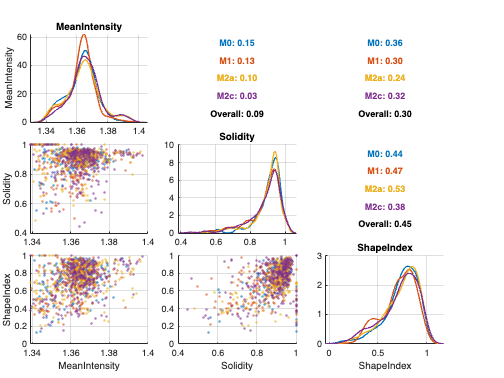

% Load the data
data = readtable('metadata.csv');

% Convert 'Type' to a categorical variable
data.Types = categorical(data.Types);

% Extract variable names for plotting
varNames = {'MeanIntensity', 'Solidity', 'ShapeIndex'};
categories = unique(data.Types);

% Create a figure for the scatter matrix
figure;

% Define colors for the categories
colors = lines(numel(categories)); % Generate distinct colors

% Resize the figure to make space for plots and spacing
%set(gcf, 'Position', [100, 100, 1200, 900]); % Increase width and height

% Define spacing for subplots
padding = 0.06; % Padding between plots
topPadding = 0.03; % Reduced top padding
bottomPadding = 0.15; % Additional padding at the bottom
plotSize = (1 - topPadding - bottomPadding - (numel(varNames) - 1) * padding) / numel(varNames);

% Loop through each variable pair for plotting
for i = 1:numel(varNames)
    for j = 1:numel(varNames)
        % Adjust subplot positions with reduced top padding
        posX = padding + (j-1) * (plotSize + padding);
        posY = 1 - (topPadding + i * (plotSize + padding));
        subplot('Position', [posX, posY, plotSize, plotSize]);
        
        if i == j
            % Diagonal: KDE-like density plots for each category
            grid on;
            hold on;
            for k = 1:numel(categories)
                subset = data.(varNames{i})(data.Types == categories(k));
                [f, xi] = ksdensity(subset); % Kernel density estimate
                plot(xi, f, 'LineWidth', 1.5, 'Color', colors(k, :));
            end
            hold off;
            title(varNames{i}, 'FontSize', 12);
        elseif i > j
            % Lower triangle: Scatter plots
            grid on;
            hold on;
            for k = 1:numel(categories)
                scatter(data.(varNames{j})(data.Types == categories(k)), ...
                        data.(varNames{i})(data.Types == categories(k)), ...
                        7.5, colors(k, :), 'filled', 'MarkerFaceAlpha', 0.6);
            end
            hold off;
        else
            % Upper triangle: Display correlation values for each type
            hold on;
            for k = 1:numel(categories)
                subsetX = data.(varNames{j})(data.Types == categories(k));
                subsetY = data.(varNames{i})(data.Types == categories(k));
                corrCoeffType = corr(subsetX, subsetY);
                text(0.5, 0.9 - (k-1)*0.2, ...
                     sprintf('%s: %.2f', char(categories(k)), corrCoeffType), ...
                     'Units', 'normalized', 'HorizontalAlignment', 'center', ...
                     'FontSize', 10, 'FontWeight', 'bold', 'Color', colors(k, :));
            end
            % Add overall correlation
            overallCorr = corr(data.(varNames{j}), data.(varNames{i}));
            text(0.5, 0.1, sprintf('Overall: %.2f', overallCorr), ...
                 'Units', 'normalized', 'HorizontalAlignment', 'center', ...
                 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'k');
            hold off;
            set(gca, 'Visible', 'off'); % Hide axis
        end
        
        % Improve layout
        if j == 1
            ylabel(varNames{i}, 'FontSize', 10);
        end
        if i == numel(varNames)
            xlabel(varNames{j}, 'FontSize', 10);
        end
        set(gca, 'FontSize', 10);
    end
end

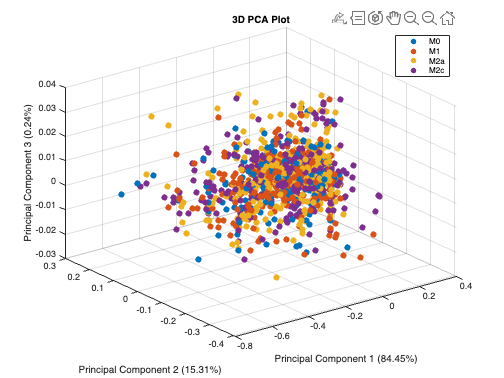

% Load the data
data = readtable('metadata.csv');

% Extract numerical data for PCA
numericalData = table2array(data(:, 2:4));

% Extract unique types for coloring purposes
types = data.Types;
uniqueTypes = unique(types);

% Perform PCA
[coeff, score, ~, ~, explained] = pca(numericalData);

% Create a scatter plot with different colors for each type
figure;
hold on;
colors = lines(length(uniqueTypes)); % Generate distinct colors for each type

% Plot data for each type with a unique color
for i = 1:length(uniqueTypes)
    typeIdx = strcmp(types, uniqueTypes{i}); % Find indices for the current type
    scatter3(score(typeIdx, 1), score(typeIdx, 2), score(typeIdx, 3), 50, ...
             colors(i, :), 'filled', 'DisplayName', uniqueTypes{i});
end

% Add labels, title, legend, and grid
xlabel(['Principal Component 1 (' num2str(explained(1), '%.2f') '%)']);
ylabel(['Principal Component 2 (' num2str(explained(2), '%.2f') '%)']);
zlabel(['Principal Component 3 (' num2str(explained(3), '%.2f') '%)']);
title('3D PCA Plot');
legend show;
grid on;

% Ensure the plot uses a 3D view
view(3);
hold off;